# EE 521 Newton Raphson Power Flow

#### `README`

`Make sure to set MATLAB's working directory as the location of ee521_powerFlow.mlx`

`Currently the NRPF algorithm does NOT support bus type conversion. This obviously affects convergence for bigger bus systems, but fortunately does not seem to affect the 14 and 30 bus systems.`

`Currently it converges for the 14 and 30 bus systems, has trouble with 57 bus system for a couple of buses and blows up for the 118 bus system. I have added another small 3 bus system called koth3 (from Kothari and Nagrath's Modern Power System Analysis) for sanity checks, which converges.`

$N$` bus systems with individual bus numbers `$i$` outside `$[1, N]$`, `$i \in \mathbb{N}$` are currently NOT supported. The ieee300 bus system is one such system.`

### Preamble and Control Inputs

tic;
addpath functions\ %all functions are stored in this folder.
% ieee300 removed from systemName variable options due to poor compatibility. 
% Current algorithm does NOT support N bus systems with bus numbers outside of natural numbers 1 to N.
systemName = "ieee30"; 
powerFlowMethod =  "NRPF" 

powerFlowMethod = "NRPF"

useSparseDSA = false;
includeOPFScenarios = false;
showOPFFormulae = false;
showOPFValues = false;
numIterations = 50; %I don't wait for the system to converge, 
printPowerFlowConvergenceMessages = false;
% neither do I care if the system converges earlier.
toleranceLimit = 1e-4; %mean of absolute values of 
% corrections should be less than this for convergence to be achieved.
displayRawData = false;
displayYBus = false;
displayTables = true; %show busData, branchData, ybus, 
% basically data structures which are not the final output.
printJacobians = false; %Print Jacobians during NRPF iterations? Does not work if displayTables is off.
printMismatches = false; %Print Mismatches during NRPF iterations? Does not work if displayTables is off.
printCorrections = false;
disableTaps = false; %Disable Tap-changers when commputing YBus?
showPlots = true;
reducedBranchColumnsCDFReading = true; %Don't read last few branchData columns in CDF files 
% as they are NOT consistent between different CDF files and may cause error in this program.
% (NOTE: Power Flow NOT affected in any way by checking this option.)
showImages = true; %might add iteration specific images later. 
verboseCDFReading = false; %Will give a verbose output when reading CDF files.
MVAb = 100; %Currently the same for all systems in database.

folder_rawData = "rawData/"; %location of CDF .txt file for the system
file_rawData = strcat(folder_rawData, systemName, "cdf.txt"); %Exact location of CDF .txt file for the system

% Should configure it to be read from the CDF file later.
latex_interpreter %for LaTeX typesetting in plots

### Read CDF file and store the data in neat MATLAB `tables: busData `and `branchData`.

[busData, branchData, N, numBranch] = ...
    readCDF(file_rawData, reducedBranchColumnsCDFReading, verboseCDFReading);
if displayTables && displayRawData
    busData
    branchData
    N
    numBranch
end

### Extract $Y_{Bus}$,  Adjacency List $E$ from the `branchData table.`

if useSparseDSA
    ybusTableFull = constructSparseYBusTable(busData, branchData);
    [nnzYBus, NYBus] = sparmat(ybusTableFull);
    if displayTables && displayYBus
        display(ybusTableFull);
        display(nnzYBus);
    end
elseif strcmp(powerFlowMethod, 'NRPF') || strcmp(powerFlowMethod, 'Decoupled NRPF')
    [ybus, BMatrix, ~, ~, ~, E] = ybusGenerator(busData, branchData);
elseif strcmp(powerFlowMethod, 'DC Power Flow')
    [ybus, BMatrix, b, A, branchNames, E] = ybusGenerator(busData, branchData);
elseif strcmp(powerFlowMethod, 'Fast Decoupled NRPF')
    [ybus, BMatrix, ~, ~, ~, E] = ybusGenerator(busData, branchData);
%     array2table(BMatrix)
end

if ~useSparseDSA && displayTables && displayYBus
    ybusTable = array2table(ybus, VariableNames=[string(1:N)], RowNames=[string(1:N)]) %#ok<UNRCH> 
    BMatrixTable = array2table(BMatrix, VariableNames=[string(1:N)], RowNames=[string(1:N)])
    if strcmp(powerFlowMethod, 'DC Power Flow')
        BMatrixTable = array2table(BMatrix, VariableNames=[string(1:N)], RowNames=[string(1:N)])
        ATable = array2table(A, VariableNames=[string(1:N)], RowNames=branchNames)
        bTable = array2table(b, VariableNames=branchNames, RowNames=branchNames)
    end
end


### Run Newton Raphson Power Flow and obtain a steady state snapshot of the system variables $P_i, Q_i, V_i, \delta_i$ $\forall$ buses $i \in [1, N], i \in \mathbb{N}$

[PSpecified, QSpecified, V, delta, ...
    listOfPQBuses, listOfPVBuses, nPQ, nPV, ...
    listOfNonSlackBuses] = initializeVectors(busData, N, MVAb);
 
if useSparseDSA    
    [deltaP, deltaQ] = computeMismatchesViaSparseYBus(...
        PSpecified, QSpecified, V, delta, ...
        nnzYBus, NYBus);
    P = PSpecified - deltaP;
    Q = QSpecified - deltaQ;
    JTable = constructSparseJacobian(...
        busData, P, Q, V, delta, ...
        nnzYBus, NYBus)
    [nnzJ, NJ] = sparmat(JTable)
    [LTable, UTable] = factorizeSparseLU(nnzJ, NJ)
else
    [P, Q, V, delta] = solveForPowerFlow(...
        PSpecified, QSpecified, V, delta, ...
        ybus, BMatrix, E, N, nPQ, nPV, ...
        listOfPQBuses, listOfNonSlackBuses, ...
        numIterations, toleranceLimit, powerFlowMethod, ...
        displayTables, printJacobians, printMismatches, printPowerFlowConvergenceMessages);
end

Convergence using NRPF achieved in 3 iterations.


### Compare obtained snapshot values of $V_i$ and $\delta_i$ against the ones given in the CDF file.

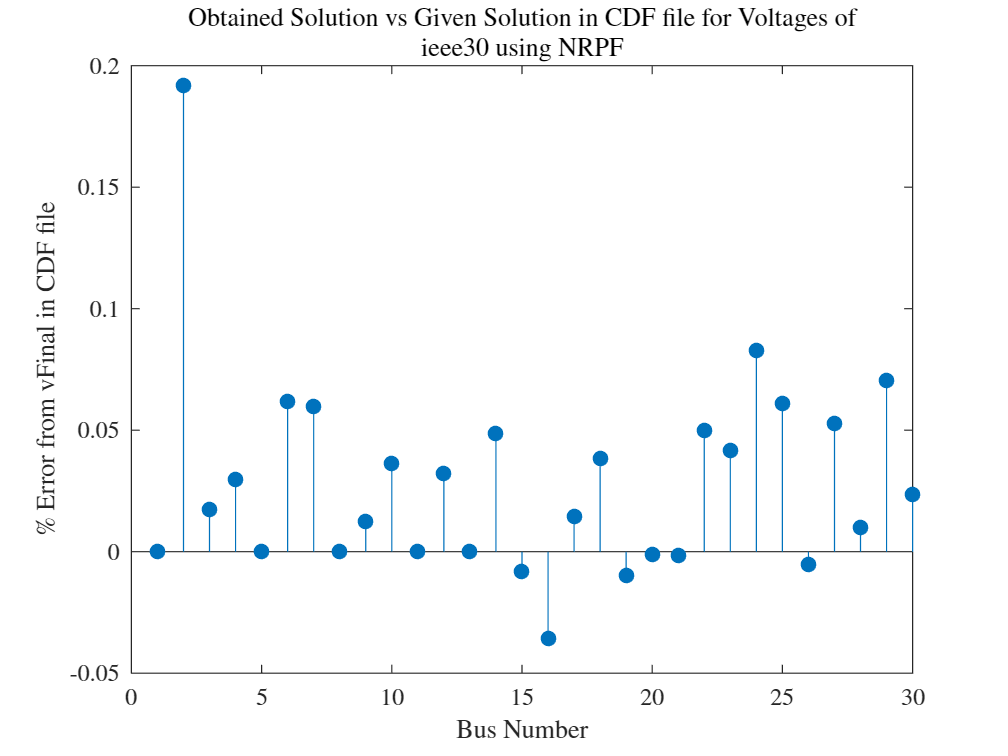

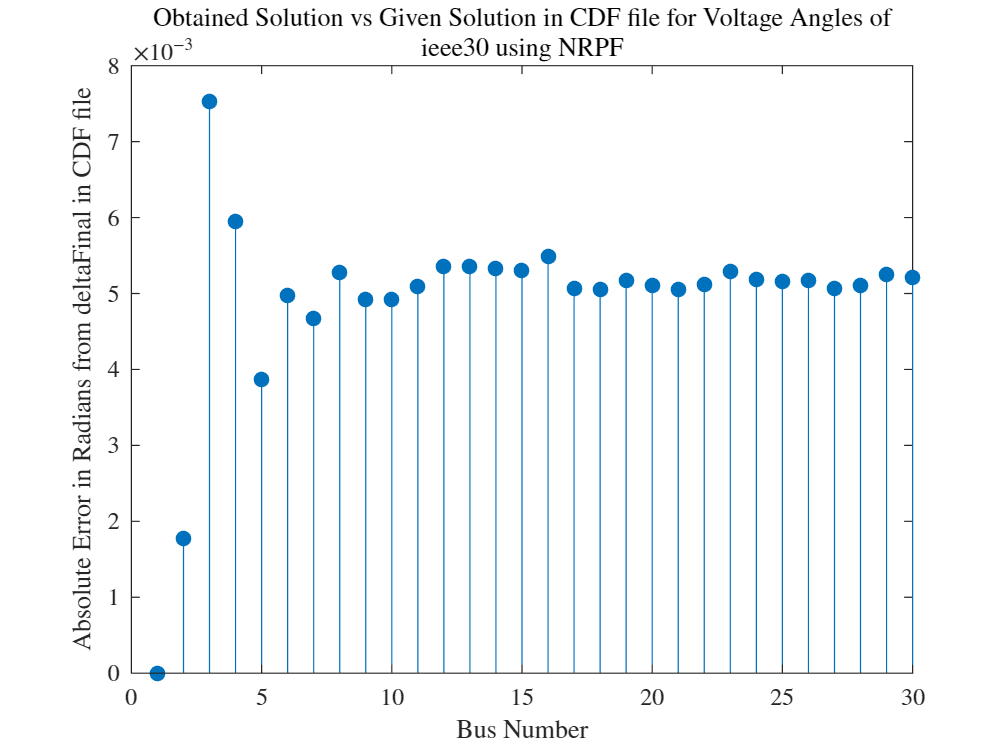

if showPlots && ~useSparseDSA
    figure('Name', 'Plot for Converged Voltage Magnitudes');
    voltagePercentageError = ((V-busData.vFinal)./busData.vFinal)*100;
    stem(voltagePercentageError, 'filled');
    xlabel('Bus Number');
    ylabel('$\%$ Error from vFinal in CDF file');
    title({'Obtained Solution vs Given Solution in CDF file for Voltages of '; systemName + ' using ' + powerFlowMethod});
    
    figure('Name', 'Plot for Converged Voltage Angles');
    deltaError = delta-(busData.deltaFinal*pi/180);
    stem(deltaError, 'filled');
    xlabel('Bus Number');
    ylabel('Absolute Error in Radians from deltaFinal in CDF file');
    title({'Obtained Solution vs Given Solution in CDF file for Voltage Angles of '; systemName + ' using ' + powerFlowMethod});
end

### Economic Dispatch and Optimal Power Flow Calculations:

if includeOPFScenarios && ~useSparseDSA
    CostCoeffs = [8.0 0.0040; 6.4 0.0048];
    PtotVals = [259, (P(1) + P(2) + busData.PL(2)/MVAb)*MVAb]';
    verbose = true;
    for itr = 1:2
        PtotVal = PtotVals(itr);
        fprintf('Economic Dispatch for Total Power = %f MW', PtotVal)
        [P_1, P_2, Cost, lambdaVal] = ...
            solveForEconomicDispatch(CostCoeffs, PtotVal);
    end
    PG0 = [P_1; P_2];
    busNums = [1 2];
    gamma = 1;
    syms delta_2
    eq0 = PtotVals(2) == busData.PL(2) + MVAb*(real(ybus(2,2))*V(2)^2 + abs(ybus(2,1)*V(1)*V(2))*cos(angle(ybus(2,1)) + delta_2));
    delta_2_Solutions = solve(eq0, delta_2);
    delta_2_Val = delta_2_Solutions(1);
    [J, JTable] = constructJacobian(P, Q, ...
        V, delta, N, ybus, BMatrix, E, ...
        nPQ, nPV, listOfPQBuses, listOfNonSlackBuses, powerFlowMethod, 'both');
    QG0 = [Q(1); Q(2)]*MVAb; %reactive power result of standard load flow

    for itr = 3:4
        if itr == 3
            fprintf('Running OPF without factoring Line Flow Limits.\n');
            penalty = false;
        elseif itr == 4
            fprintf('Running OPF with constraint of P12 <= 5 MW\n');
            penalty = true;
        end
        [P_1, P_2, Cost] = ...
            solveForOPF(busNums, PG0, QG0, MVAb, delta_2_Val, delta, V, listOfPQBuses, ybus, E, J, ...
            busData, CostCoeffs, penalty, gamma, showOPFFormulae, showOPFValues, printPowerFlowConvergenceMessages);
    end
end
toc;

Elapsed time is 0.727400 seconds.


# Have a nice day! 

In case you encounter a Java Heap Memory error, delete the above gif, or go to `Preferences->General->Java Heap Memory` and increase the allocated size.